Signal 10: 21:34 Error position for the width [mm]

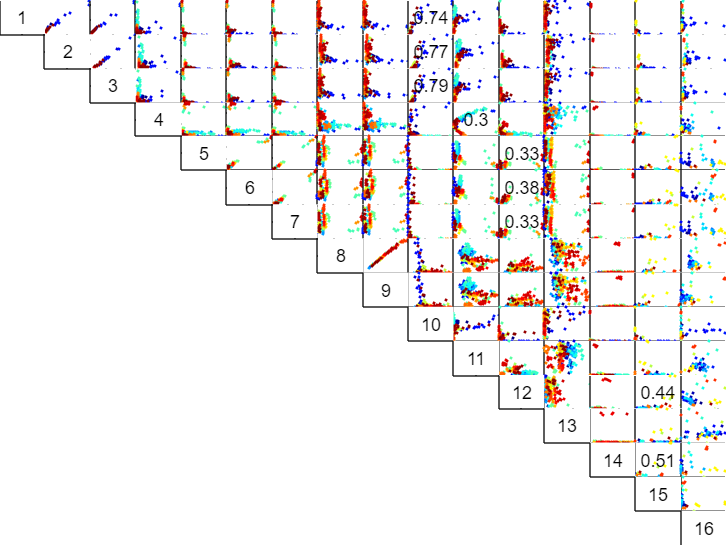

lowerR2 = 0.3;
upperR2 = 0.8;
r2ReducedThreshold = 0.9;
selectedSignal = 10; % 21:34 & Error position for the width
saveFigures = true;
R2 = fnPlotFeatureVsFeature_Array(featureArray_Standard, lowerR2, upperR2, selectedSignal, FeatureNames_Combined, sensorNames);

disp(num2str(R2, '%.2f  '));

1.00  0.95  0.98  0.12  0.04  0.04  0.04  0.04  0.05  0.74  0.05  0.04  0.04  0.00  0.03  0.00
0.00  1.00  0.98  0.11  0.07  0.07  0.07  0.06  0.06  0.77  0.09  0.05  0.04  0.01  0.04  0.00
0.00  0.00  1.00  0.12  0.05  0.05  0.05  0.05  0.05  0.79  0.07  0.04  0.04  0.01  0.03  0.00
0.00  0.00  0.00  1.00  0.00  0.00  0.00  0.11  0.11  0.02  0.30  0.12  0.02  0.00  0.05  0.01
0.00  0.00  0.00  0.00  1.00  0.99  1.00  0.06  0.07  0.05  0.15  0.33  0.06  0.29  0.24  0.00
0.00  0.00  0.00  0.00  0.00  1.00  0.99  0.06  0.07  0.05  0.11  0.38  0.06  0.27  0.26  0.02
0.00  0.00  0.00  0.00  0.00  0.00  1.00  0.06  0.07  0.05  0.15  0.33  0.06  0.29  0.25  0.00
0.00  0.00  0.00  0.00  0.00  0.00  0.00  1.00  0.99  0.05  0.13  0.12  0.15  0.04  0.05  0.23
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  1.00  0.06  0.14  0.13  0.17  0.05  0.05  0.21
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  1.00  0.02  0.02  0.06  0.01  0.04  0.00
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.

## Combination 1

selectedFeature = 1;
[selectedFeatureArray, selectedFeatureData, numOfSelectedFeatures] = fnSelectFeatures(selectedSignal, selectedFeature, featureArray_Standard,R2, upperR2, lowerR2, r2ReducedThreshold, true);

     1    10
     1    10


figure(); hold on;
sensorNames(selectedSignal)%title(sensorNames(selectedSignal));

ans = "21:34 Error position for the width [mm]"

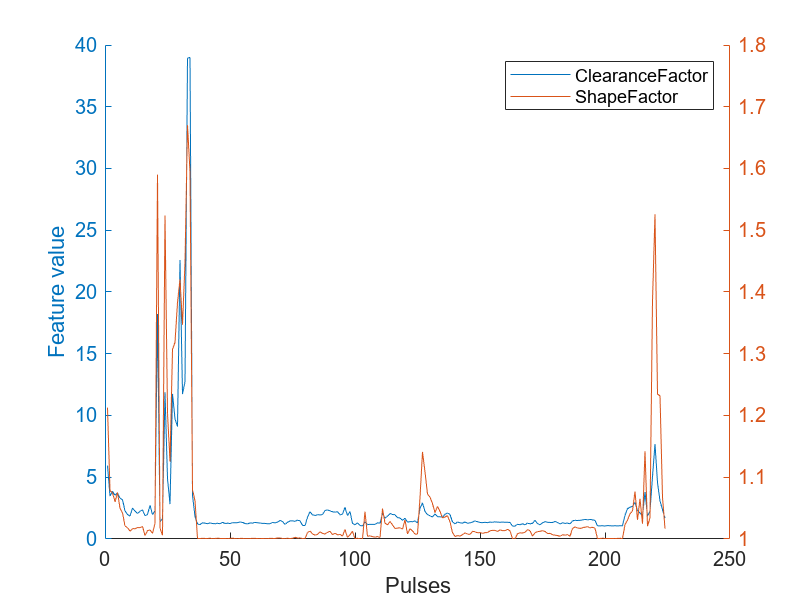

xlabel("Pulses");
ylabel("Feature value");
leg = {numOfSelectedFeatures};
secondaryAxisArrayIndex = [2];
legendAxis = [];
for i = 1:numOfSelectedFeatures
    if ismember(i, secondaryAxisArrayIndex)
        yyaxis right;
        ha = plot(selectedFeatureData{i});
        legendAxis = [legendAxis ha];
    else
        yyaxis left;
        hb = plot(selectedFeatureData{i});
        legendAxis = [legendAxis hb];
    end
    leg{i} = char(FeatureNames_Combined(selectedFeatureArray(i)));
end
hold off;
legend(legendAxis, leg)

if (saveFigures == true)
    filename = "..\Latex Document\figures\Models_Signal" + selectedSignal + "Feature" + selectedFeature;
    print(filename,'-depsc','-tiff')
end

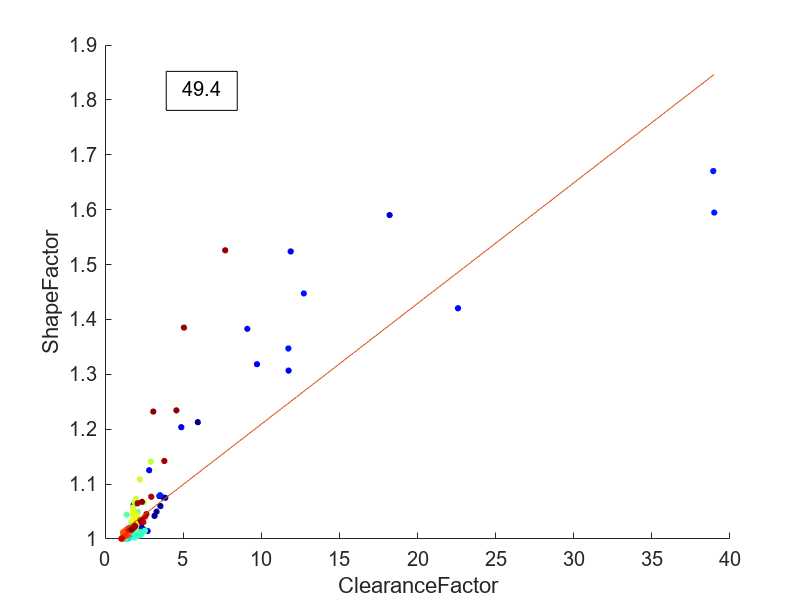

selectedFeatureIdx = find(selectedFeatureArray == selectedFeature);
linearModelNum = 1;
for index = 1 : numOfSelectedFeatures
    if selectedFeatureArray(index) ~= selectedFeature
        fnPlotModel(selectedFeatureData{index}, ...
            selectedFeatureData{selectedFeatureIdx}, ...
            sensorNames(selectedSignal), ...
            FeatureNames_Combined(selectedFeatureArray(index)), ...
            FeatureNames_Combined(selectedFeature));
        if (saveFigures == true)
            filename = "..\Latex Document\figures\Models_Signal" + selectedSignal ...
                + "Feature" + selectedFeature ...
                + "_Linear" + linearModelNum;
            export_fig(filename, '-eps', '-depsc');
            linearModelNum = linearModelNum + 1;
        end
    end
end

multivariateModelNum = 1;
if numOfSelectedFeatures > 2
    for index1 = 1 : numOfSelectedFeatures
        for index2 = index1+1 : numOfSelectedFeatures
            if selectedFeatureArray(index1) ~= selectedFeature && selectedFeatureArray(index2) ~= selectedFeature            
                Y_est = fnPlotModel3D( ...
                    selectedFeatureData{selectedFeatureIdx}, ...
                    selectedFeatureData{index1}, ...
                    selectedFeatureData{index2}, ...
                    sensorNames(selectedSignal), ...
                    FeatureNames(selectedFeatureArray(selectedFeatureIdx)), ...
                    FeatureNames(selectedFeatureArray(index1)), ...
                    FeatureNames(selectedFeatureArray(index2)));
                if (saveFigures == true)
                    filename = "..\Latex Document\figures\Models_Signal" + selectedSignal ...
                        + "Feature" + selectedFeature ...
                        + "_Multivariate" + multivariateModelNum;
                    %export_fig(filename, '-eps', '-depsc');
                    print(filename, '-depsc');
                    multivariateModelNum = multivariateModelNum + 1;
                end
            end
        end
    end
end

## Combination 2

selectedFeature = 11;
[selectedFeatureArray, selectedFeatureData, numOfSelectedFeatures] = fnSelectFeatures(selectedSignal, selectedFeature, featureArray_Standard,R2, upperR2, lowerR2, r2ReducedThreshold, true);

     4    11
     4    11


figure(); hold on;
sensorNames(selectedSignal)%title(sensorNames(selectedSignal));

ans = "21:34 Error position for the width [mm]"

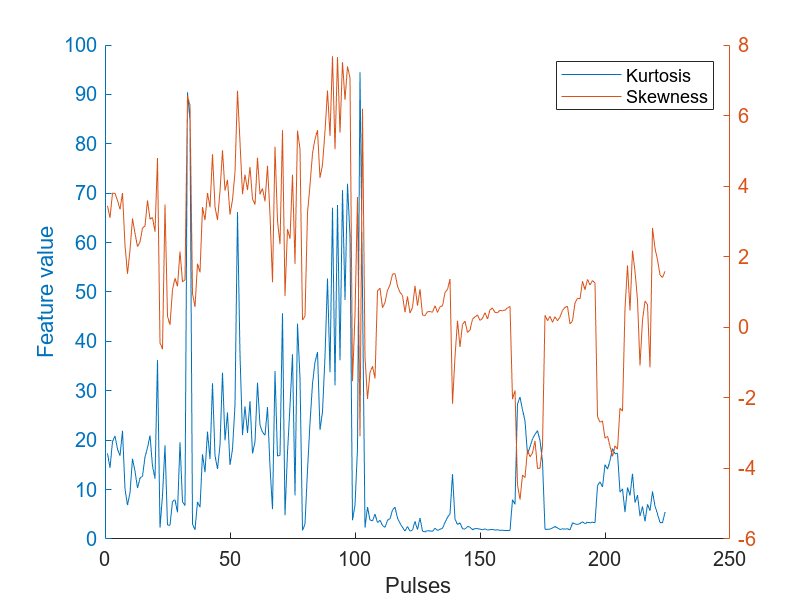

xlabel("Pulses");
ylabel("Feature value");
leg = {numOfSelectedFeatures};
secondaryAxisArrayIndex = [2];
legendAxis = [];
for i = 1:numOfSelectedFeatures
    if ismember(i, secondaryAxisArrayIndex)
        yyaxis right;
        ha = plot(selectedFeatureData{i});
        legendAxis = [legendAxis ha];
    else
        yyaxis left;
        hb = plot(selectedFeatureData{i});
        legendAxis = [legendAxis hb];
    end
    leg{i} = char(FeatureNames_Combined(selectedFeatureArray(i)));
end
hold off;
legend(legendAxis, leg)

if (saveFigures == true)
    filename = "..\Latex Document\figures\Models_Signal" + selectedSignal + "Feature" + selectedFeature;
    print(filename,'-depsc','-tiff')
end

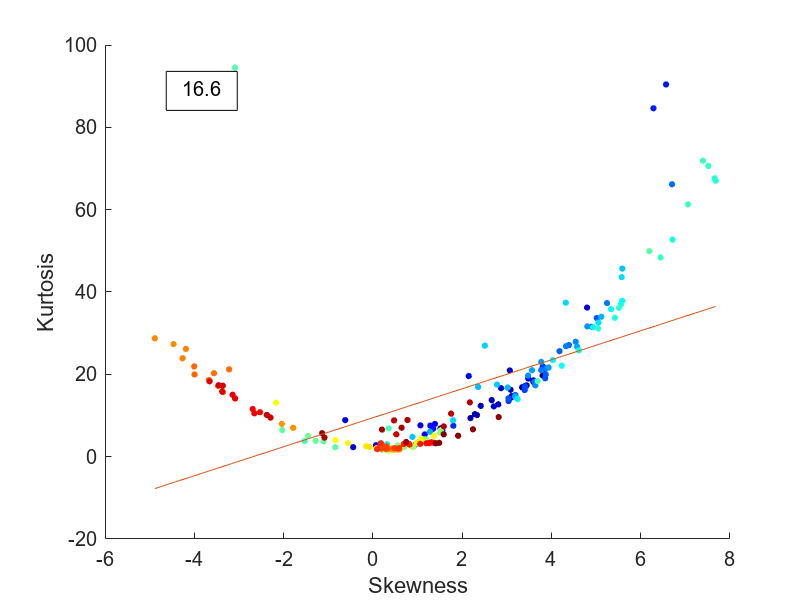

selectedFeatureIdx = find(selectedFeatureArray == selectedFeature);
linearModelNum = 1;
for index = 1 : numOfSelectedFeatures
    if selectedFeatureArray(index) ~= selectedFeature
        fnPlotModel(selectedFeatureData{index}, ...
            selectedFeatureData{selectedFeatureIdx}, ...
            sensorNames(selectedSignal), ...
            FeatureNames_Combined(selectedFeatureArray(index)), ...
            FeatureNames_Combined(selectedFeature));
        if (saveFigures == true)
            filename = "..\Latex Document\figures\Models_Signal" + selectedSignal ...
                + "Feature" + selectedFeature ...
                + "_Linear" + linearModelNum;
            %export_fig(filename, '-eps', '-depsc');
            print(filename, '-depsc');
            filename = "..\Presentation\Models_Signal" + selectedSignal ...
                + "Feature" + selectedFeature ...
                + "_Linear" + linearModelNum;
            print(filename, '-dsvg');
            linearModelNum = linearModelNum + 1;
        end
    end
end

## Combination 3

selectedFeature = 12;
[selectedFeatureArray, selectedFeatureData, numOfSelectedFeatures] = fnSelectFeatures(selectedSignal, selectedFeature, featureArray_Standard,R2, upperR2, lowerR2, r2ReducedThreshold, true);

Sig 5 Sig 6 = 0.99
Sig 5 Sig 7 = 1.00
     5     6     7    12    15
     5    12    15


figure(); hold on;
sensorNames(selectedSignal)%title(sensorNames(selectedSignal));

ans = "21:34 Error position for the width [mm]"

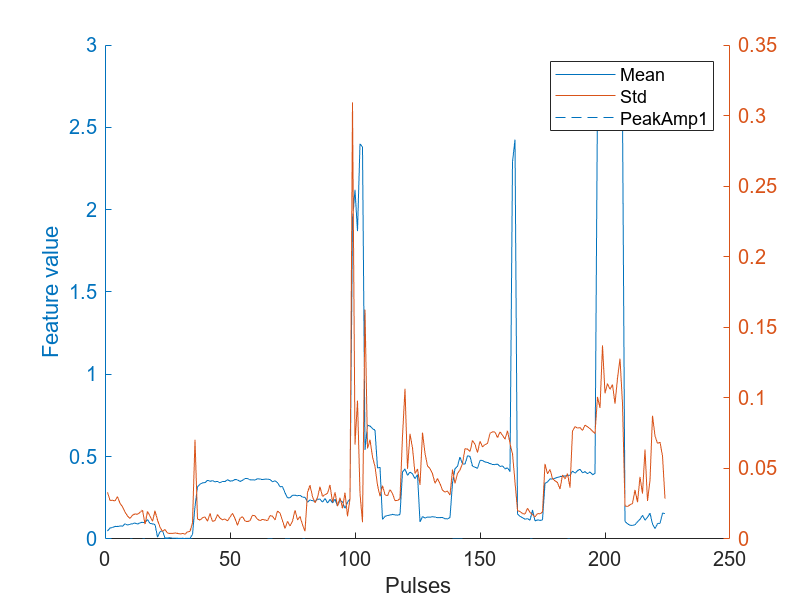

xlabel("Pulses");
ylabel("Feature value");
leg = {numOfSelectedFeatures};
secondaryAxisArrayIndex = [2];
legendAxis = [];
for i = 1:numOfSelectedFeatures
    if ismember(i, secondaryAxisArrayIndex)
        yyaxis right;
        ha = plot(selectedFeatureData{i});
        legendAxis = [legendAxis ha];
    else
        yyaxis left;
        hb = plot(selectedFeatureData{i});
        legendAxis = [legendAxis hb];
    end
    leg{i} = char(FeatureNames_Combined(selectedFeatureArray(i)));
end
hold off;
legend(legendAxis, leg)

if (saveFigures == true)
    filename = "..\Latex Document\figures\Models_Signal" + selectedSignal + "Feature" + selectedFeature;
    print(filename,'-depsc','-tiff')
end

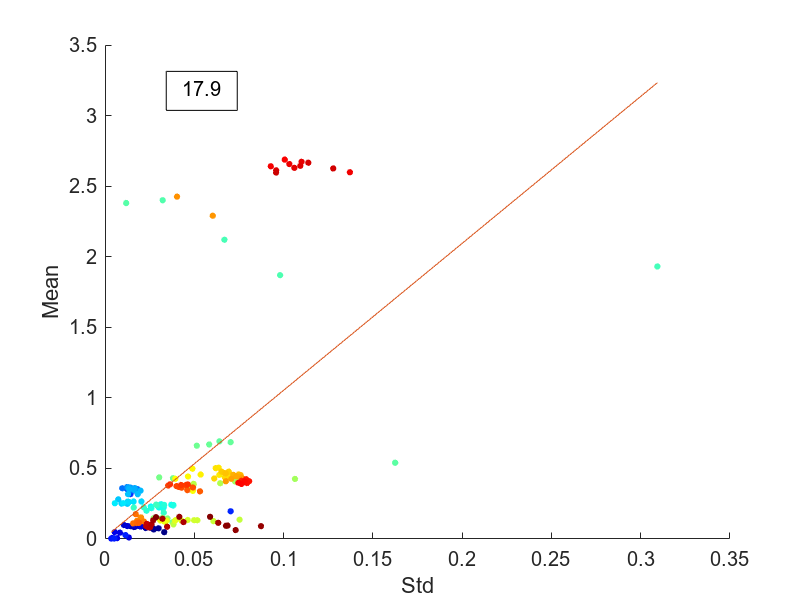

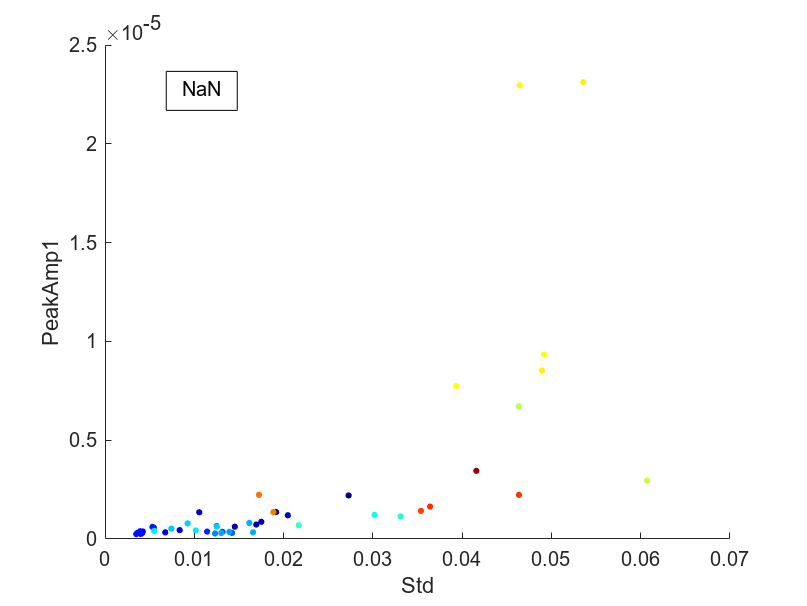

selectedFeatureIdx = find(selectedFeatureArray == selectedFeature);
linearModelNum = 1;
for index = 1 : numOfSelectedFeatures
    if selectedFeatureArray(index) ~= selectedFeature
        fnPlotModel(selectedFeatureData{index}, ...
            selectedFeatureData{selectedFeatureIdx}, ...
            sensorNames(selectedSignal), ...
            FeatureNames_Combined(selectedFeatureArray(index)), ...
            FeatureNames_Combined(selectedFeature));
        if (saveFigures == true)
            filename = "..\Latex Document\figures\Models_Signal" + selectedSignal ...
                + "Feature" + selectedFeature ...
                + "_Linear" + linearModelNum;
            %export_fig(filename, '-eps', '-depsc');
            print(filename, '-depsc');
            linearModelNum = linearModelNum + 1;
        end
    end
end